# Eye Model Development

## Introduction

Establish optical foundation using Arizona Model and expand upon it with other relevant anatomical properties.

### Source(s) of Truth

- `lensData` (radius of curvature, refractive index, thickness, etc.)

- Iris size and position

### Derived Value(s)

- Entrance and exit pupil properties (position, magnification, size, etc.)

- Eye centroid

- Anterior Chamber Depth

- Axial length

- Powers and focal lengths

- Retinal magnification factor

Initialize the eye-model in relaxed state and display it a table. 

clearvars
A = 0;  % Diopters of accommodation
model = Arizona(A);
model.data

ans = 6×6 table
     Surface      Radius    Thickness    Index    SemiDiameter    Conic
    __________    ______    _________    _____    ____________    _____

    "OBJ"            Inf       5.00      1.00         5.00         0.00
    "Cornea"        7.80       0.55      1.38         6.00        -0.25
    "Aqueous"       6.50       2.97      1.34         6.00        -0.25
    "Lens"         12.00       3.77      1.42         5.00        -7.52
    "Vitreous"     -5.22      16.71      1.34         5.00        -1.35
    "Retina"      -13.40       0.00      0.00         0.50         0.00


Surfaces are modeled by the conic equation:


$$z = \frac{y^2/R}  {1 +  \sqrt{1 - (K+1) \frac{y^2}{R^2} } }$$


This alternative expression is used where conic constant $K \not=-1$:


$$z = \frac{1}{K+1}[R - \sqrt{R^2 - (K+1)y^2} ] $$


## Eyeball Centroid Estimation

Conic equation written as radial position y as a function of sag is the "upper-half" inverse of standard form:


$$y = \sqrt{ \frac{R^2 - (z(K+1) - R)^2} {K+1}     } $$


Only only upper half is required because we assume a perfectly symmetric eye, expression for the centroid becomes:


$$c = \frac{ \int_{0}^{acd}zc(z)dz + \int_{acd}^{al}zs(z)dz} {\int_{0}^{acd}c(z)dz + \int_{acd}^{al}s(z)dz }$$


We only need to evaluate$\int_{}^{}zc(z)dz$ because characteristic functions $c(z)$ and $s(z)$ only differ in their *K *value. The result is the following integral which we can look up closed-form [solution](https://en.wikipedia.org/wiki/List_of_integrals_of_irrational_functions):


$$\int_{}^{}zc(z)dz = \frac{1}{(K+1)^{5/2}} \int{[u \sqrt{R^2 - u^2}du} + R\sqrt{R^2 - u^2}du]$$


where the following "u-substitution" is used:


$$u=z(K+1)-R \Longrightarrow dz \rightarrow \frac{du}  {K+1}$$


Integral $\int_{}^{}c(z)dz$ is the measure on the set captured by charateristic function $c(z)$, which can be expressed as the following with the same "u-substitution" as above:


$$\int_{}^{}c(z)dz = \frac{1}{(K+1)^{3/2}} \int{\sqrt{R^2-u^2}du}$$


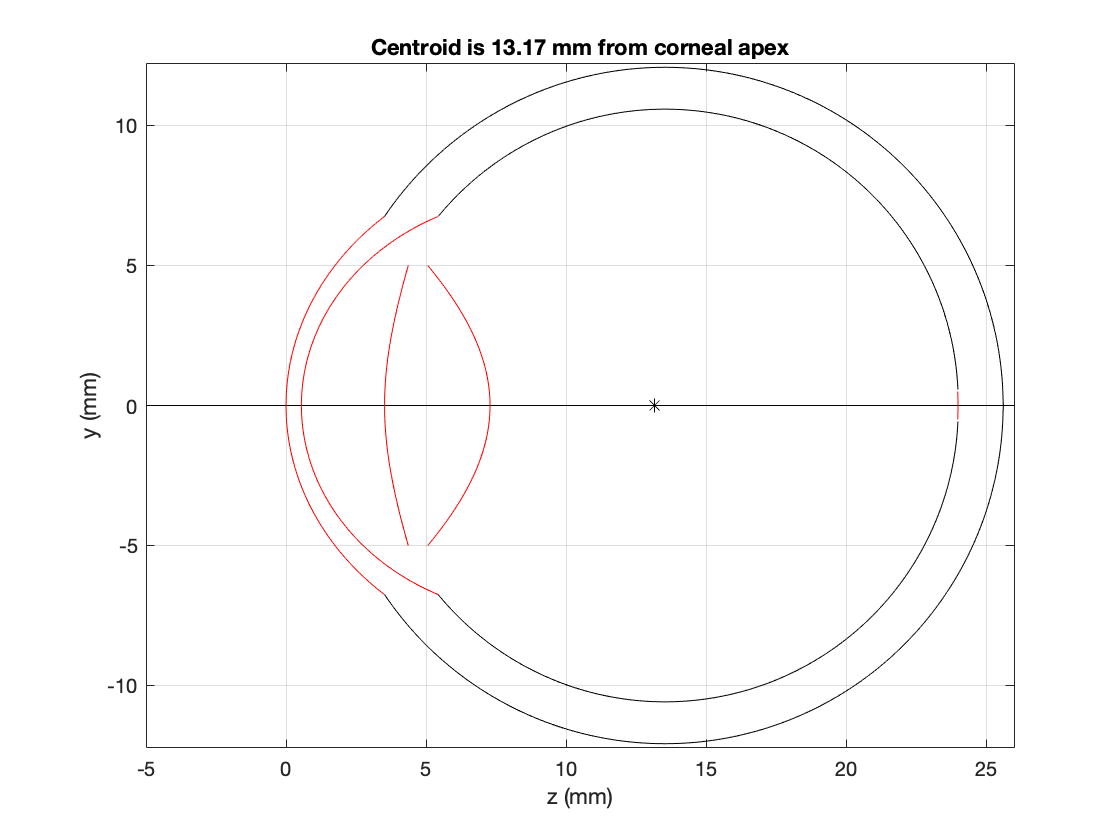

clearvars
model = Arizona();
model.draw(true);
hold on
scatter(model.centroid, 0, 'k*');
title(sprintf("Centroid is %1.2f mm from corneal apex", model.centroid))
hold off

## Eye movement patterns during convergence

Linear translation during eye rotation has been known for a long time but assumed to be negligible. It is assumed equal and opposite eye movement pattern occurs during divergence.

### Eye Centroid Movement

Gaze change causes complex 3D movements of the eyeball because it's not fixed to a shaft-like structure. Depending on the magnitude of adduction gaze change, the eye centroid may linearly translate nasally. 

Moon, Yeji, et al. "Positional Change of the Eyeball During Eye Movements: Evidence of Translatory Movement." *Frontiers in Neurology* 11 (2020): 1081.

clearvars
model = Arizona;
model.entrancePupil

ans = struct with fields:
    magnification: 1.13
         position: 2.96


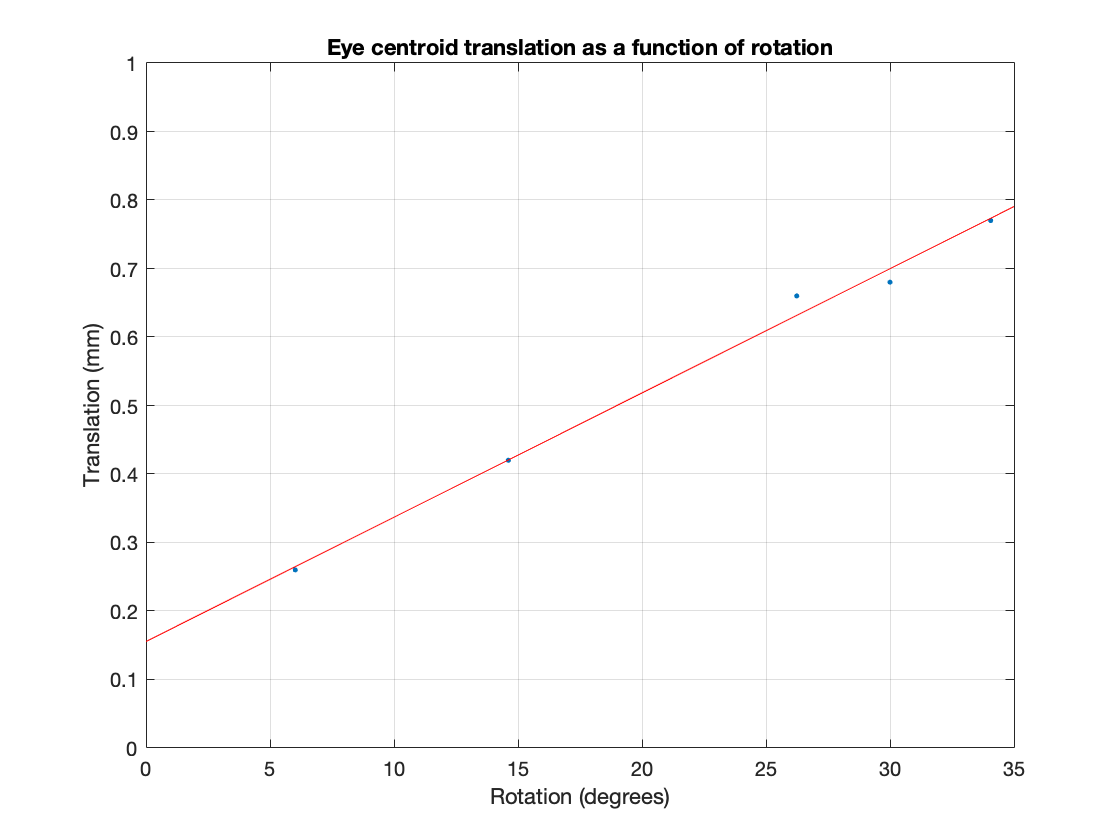

z = 442.9;  % eye-to-fixation distance (mm)
od = 31.32; % monocular pd (mm)
t = asind(od/z);
% Considering taking the matte image and generating a contour from it
x_data = [6.02; 14.61; 26.24; 30; 34.06]; % rotation (deg)
y_data = [0.26; 0.42; 0.66; 0.68; 0.77]; % translation (mm)

p = polyfit(x_data,y_data,1);
x = (0:35)';
y = polyval(p,x);
% Convention - convergence means positive angle change
plot(x_data,y_data, '.',x,y,'r')
ylim([0 1])
title("Horizontal Eye centroid translation as a function of rotation")
xlabel("Rotation (degrees)"), ylabel("Translation (mm)")
grid on

## Verification

Tests below are numerical checks to ensure eye-model implimentation to be accurate

clearvars
model = Arizona; % unaccommodate Arizonal Eye Model

### Anatomy (Tests 1-4)

#### 1. Axial Length

Nominal axial length is approximately 24 mm

al = model.axialLength;
if abs(round(al) - 24) < eps
    fprintf('Pass: axial length (%1.2f mm)', al)
else
    fprintf("Fail: axial length")
end

Pass: axial length (24.00 mm)

#### 2. Scleral Thickness

TODO, as of 18JAN2021 no application with an immediate need for model with accurate scleral thickness

% Scleral thickness 0.50 +/- 0.05 mm (tentative)
% t = obj.scleralThickness;       

#### 3. Eye Centroid

Verify analytical centroid result of our eye-model implementation against numerical estimate from binary "matte" eyeball image. Analytical and numerical eye-centroid results differ less than 0.1 mm

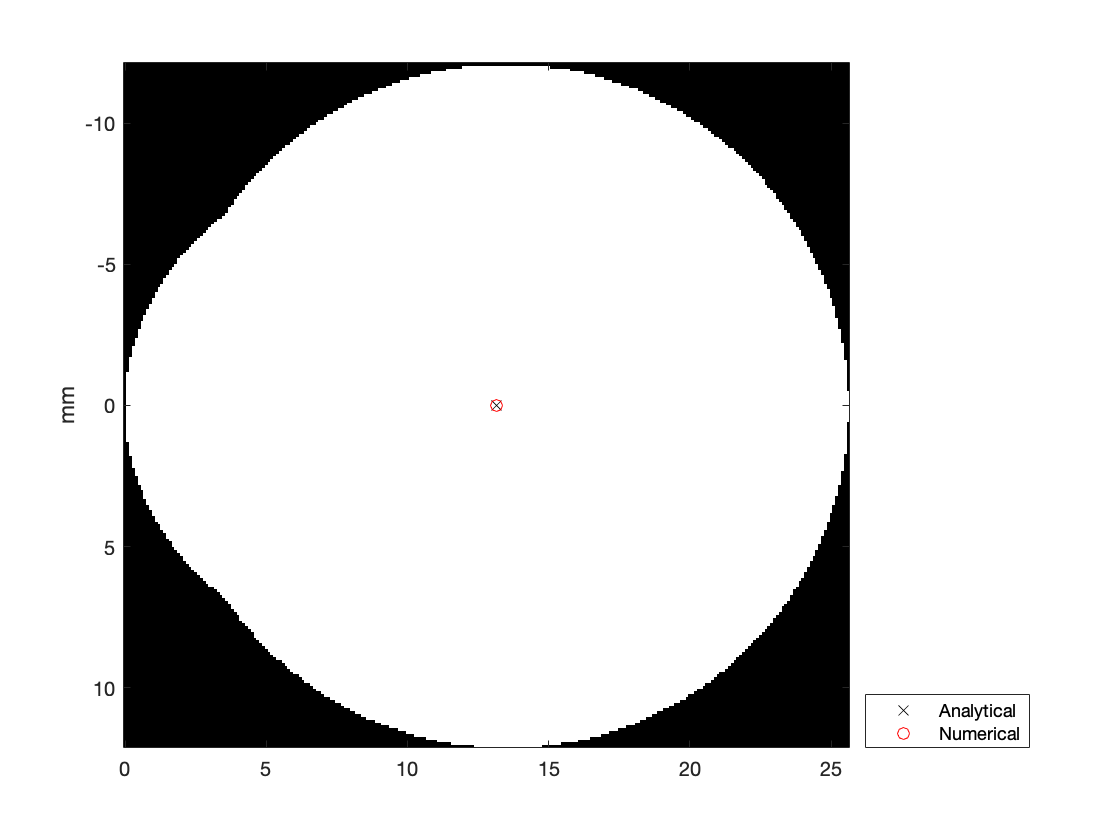

[B, Z] = model.matte();
y_data = linspace(-model.sclera.R, model.sclera.R, size(B,1));
z = Z(1,:);
imagesc(z, y_data, B)
hold on
scatter(model.centroid, 0, 'xk'), scatter(sum(sum(Z.*B)) / sum(sum(B)), 0, 'or')
legend({'Analytical', 'Numerical'}, 'location', 'southeastoutside')
hold off
ylabel("mm")
colormap gray
axis image

if abs(model.centroid - sum(sum(Z.*B)) / sum(sum(B))) < 0.1
    fprintf('Pass: eye centroid (%1.2f mm from corneal vertex)', model.centroid)
else
    fprintf('Fail: eye centroid')
end    

Pass: eye centroid (13.17 mm from corneal vertex)

#### 4. Pupil Translation

Simulate eye movement going from viewing near (40 cm) to far $(\infty)$ and back to near again. Pupil position should arrive back at the exact same location. The pupil-translation model is considered to be accurate if difference between measured near PD and estimated near PD are within 0.01 mm. 

z0 = 44.36; % near viewing distance (cm)
mpd = 31.322; % measured near monocular pd (mm)
dpd = mpd + model.pupilShiftDistance(atand(mpd / (10 * z0)));
npd = dpd - model.pupilShiftNear(z0, dpd);
if abs(npd - mpd)
    fprintf('Pass: pupil-translation model')
else
    fprintf('Fail: pupil-translation model')
end

Pass: pupil-translation model

### First-Order Optical Properties (Tests 5-8)

Verification of first-order optical properties below assumes Arizona Eye Model.

Use a pair of ray-transfer matrices for each ocular surface

 
$$M = \pmatrix{1 & d \cr 0 & 1} \pmatrix{1 & 0 \cr \frac{n_1-n_2}{R \cdot n_2 } & \frac{n_1}{n_2} }$$


#### 5. Dioptric Power

Input ray parallel to optical axis is modeled as [1; 0]:


$$v_1=Mv_0, v_0= \pmatrix{1 \cr 0}$$


Output from multiplying ray-transfer matrix can be used to compute distance from 2nd principle plane to back-focal plane:


$$H_2F_2=\frac{-1}{tan[v_1(2)]}$$


Total power of unaccommodated Arizona Eye Model is (p. 16) 60.61 D; our model's dioptric power is to be within 0.1 D from design.

p = model.dioptricPower;
if abs(p - 60.61) < 0.1
    fprintf('Pass: dioptric power (%1.2f D)', p)
else
    fprintf('Fail: dioptric power')
end

Pass: dioptric power (60.66 D)

#### 6. Pupil Magnifications

Entrance and exit pupil (lateral) magnifications are greater than one

if (model.entrancePupil().magnification > 1) && (model.exitPupil().position > 1)
    fprintf('Pass: entrance and exit pupil magnification (m > 1)')
else
    fprintf('Fail: entrance and exit pupil magnification')
end

Pass: entrance and exit pupil magnification (m > 1)

Entrance pupil position is inside aqueous humor ($0.55<z_{pupil} < 3.52 $mm)

acd = 3.52; % anterior chamber depth (mm)
z = model.entrancePupil().position;
if (z < acd) && (z > 0.55)
    fprintf('Pass: entrance pupil position is %1.2f mm in front of iris plane', acd - z)
else
    fprintf('Fail: entrance pupil position')
end

Pass: entrance pupil position is 0.56 mm in front of iris plane

#### 7. Pupil Positions

Exit pupil position is within 0.1 mm of iris position

z = model.exitPupil().position;
if abs(z - acd) < 0.1
    fprintf('Pass: exit pupil position is %1.2f mm from iris plane', abs(z - acd))
else
    fprintf('Fail: exit pupil position')
end

Pass: exit pupil position is 0.07 mm from iris plane

#### Reference(s)

- Schwiegerling, Jim. "Field guide to visual and ophthalmic optics." Spie, 2004.